# SCOPES Tutorial

This tutorial shows how to use the `scopes` function to build **simultaneous confidence bands** for the mean of a random field and to convert them into nested **cope sets** (Confidence Regions for the Location of the Population Excursion Set). We use the same brain-surface simulation framework as the confidence regions tutorial: smooth noise generated on the HCP surface, scaled to match real working-memory data.

## Setup

To run this tutorial you first need to add all functions in the StatBrainz toolbox to the MATLAB path (e.g. by running `addSB2path.m` from the StatBrainz folder). The `scopes` function also depends on `fastperm` from the `matperm` package, so that must be on the path as well. Fill in the two directories below.

statsbrainz_directory_pathloc = '/Users/samd/Documents/Code/Packages/Matlab/StatBrainz/Tutorials/';
matperm_directory_pathloc     = '/Users/samd/Documents/Code/Packages/Matlab/matperm';
addpath(genpath(statsbrainz_directory_pathloc));
addpath(genpath(matperm_directory_pathloc));

## Load the HCP surface

We load the left and right inflated HCP surfaces and the mean/standard-deviation maps from a real working-memory dataset. These summaries are used to give the simulated noise a realistic spatial structure.

sb_dir = statbrainz_maindir;
path4gifti_L = [sb_dir, 'BrainImages/Gifti_files/S1200.L.inflated_MSMAll.32k_fs_LR.surf.gii'];
path4gifti_R = [sb_dir, 'BrainImages/Gifti_files/S1200.R.inflated_MSMAll.32k_fs_LR.surf.gii'];
hcp_srf = gifti2surf(path4gifti_L, path4gifti_R);
load([sb_dir,'BrainImages/Real_data/hcpWM_surface.mat'])

## Generate the data

We simulate `nsubj` subjects of smooth surface noise (smoothing FWHM of 10mm), then rescale each hemisphere so its mean and variance match the real working-memory data. `xbar` is the sample mean over subjects and `mask` flags the valid (non-NaN) vertices. We zero-fill NaNs inside the data so the permutation step is well defined.

FWHM = 10; nsubj = 50;
clear data xbar mask
data = srf_noise(hcp_srf, FWHM, nsubj);

50 x 1 surfaces to smooth, % remaining: 100 90 80 70 60 50 40 30 20 10 0 Done
50 x 1 surfaces to smooth, % remaining: 100 90 80 70 60 50 40 30 20 10 0 Done


for hemis = {'lh', 'rh'}
    h = hemis{1};
    data.(h) = (data.(h))./std(data.(h)(:));
    data.(h) = (data.(h)).*hcp_data_std.(h);
    data.(h) = data.(h) + hcp_data_mean.(h);
    xbar.(h)  = mean(data.(h),2);
    mask.(h)  = ~isnan(xbar.(h));
    xbar.(h)(~mask.(h)) = 0;
    d = data.(h); d(isnan(d)) = 0; data.(h) = d;
end

## Run SCOPES

`scopes` operates on a plain `[nvertices x nsubj]` array, so we stack the masked left- and right-hemisphere data into a single field before calling it. The signature is

where `nblocks` is the number of permutation blocks (default: the number of subjects), `nboot` is the number of permutations, and `alpha` is the (two-sided) error rate. `scopes` estimates a global threshold via a sign-flipping permutation of the demeaned data, then returns the bands

which cover the true mean field simultaneously across all vertices with probability `1 - alpha`.

alpha = 0.05; nboot = 1000;
masked_data = [data.lh(mask.lh,:); data.rh(mask.rh,:)];
[lo, up, threshold] = scopes(masked_data, size(masked_data,2), nboot, alpha, 1);

-------------------------------------------------------
fastperm progress: 100.0


fprintf('SCOPES threshold = %g\n', threshold);

SCOPES threshold = 4.98997


Unpack the stacked bands back onto the two hemispheres.

lower_band.lh = zeros(size(mask.lh)); lower_band.rh = zeros(size(mask.rh));
upper_band.lh = zeros(size(mask.lh)); upper_band.rh = zeros(size(mask.rh));
nlh = sum(mask.lh);
lower_band.lh(mask.lh) = lo(1:nlh);     lower_band.rh(mask.rh) = lo(nlh+1:end);
upper_band.lh(mask.lh) = up(1:nlh);     upper_band.rh(mask.rh) = up(nlh+1:end);

## From confidence bands to cope sets

For a chosen threshold `c`, the cope sets sandwich the true excursion set {mean > c}:

- the **subset** (vertices where even the *lower* band exceeds `c` — confidently above `c`),

- the **superset** (vertices where the *upper* band exceeds `c` — plausibly above  `c`),

- the **point estimate** {xbar > c}, whose boundary is the yellow contour.

`srf_scb2cope` performs this conversion. With probability `1 - alpha` the true excursion set lies between the subset and the superset, simultaneously over all `c`.

c = 2;
[lower_set, upper_set, contour, point_set] = ...
    srf_scb2cope(hcp_srf.lh, lower_band.lh, upper_band.lh, xbar.lh, c);
fprintf('subset = %d, point estimate = %d, superset = %d vertices\n', ...
    sum(upper_set), sum(point_set), sum(lower_set));

subset = 217, point estimate = 2280, superset = 7862 vertices


## Plot the cope sets

We colour the superset light red, the subset dark red, and draw the point-estimate contour in yellow. The dark-red region is contained in the point estimate, which is contained in the light-red region.

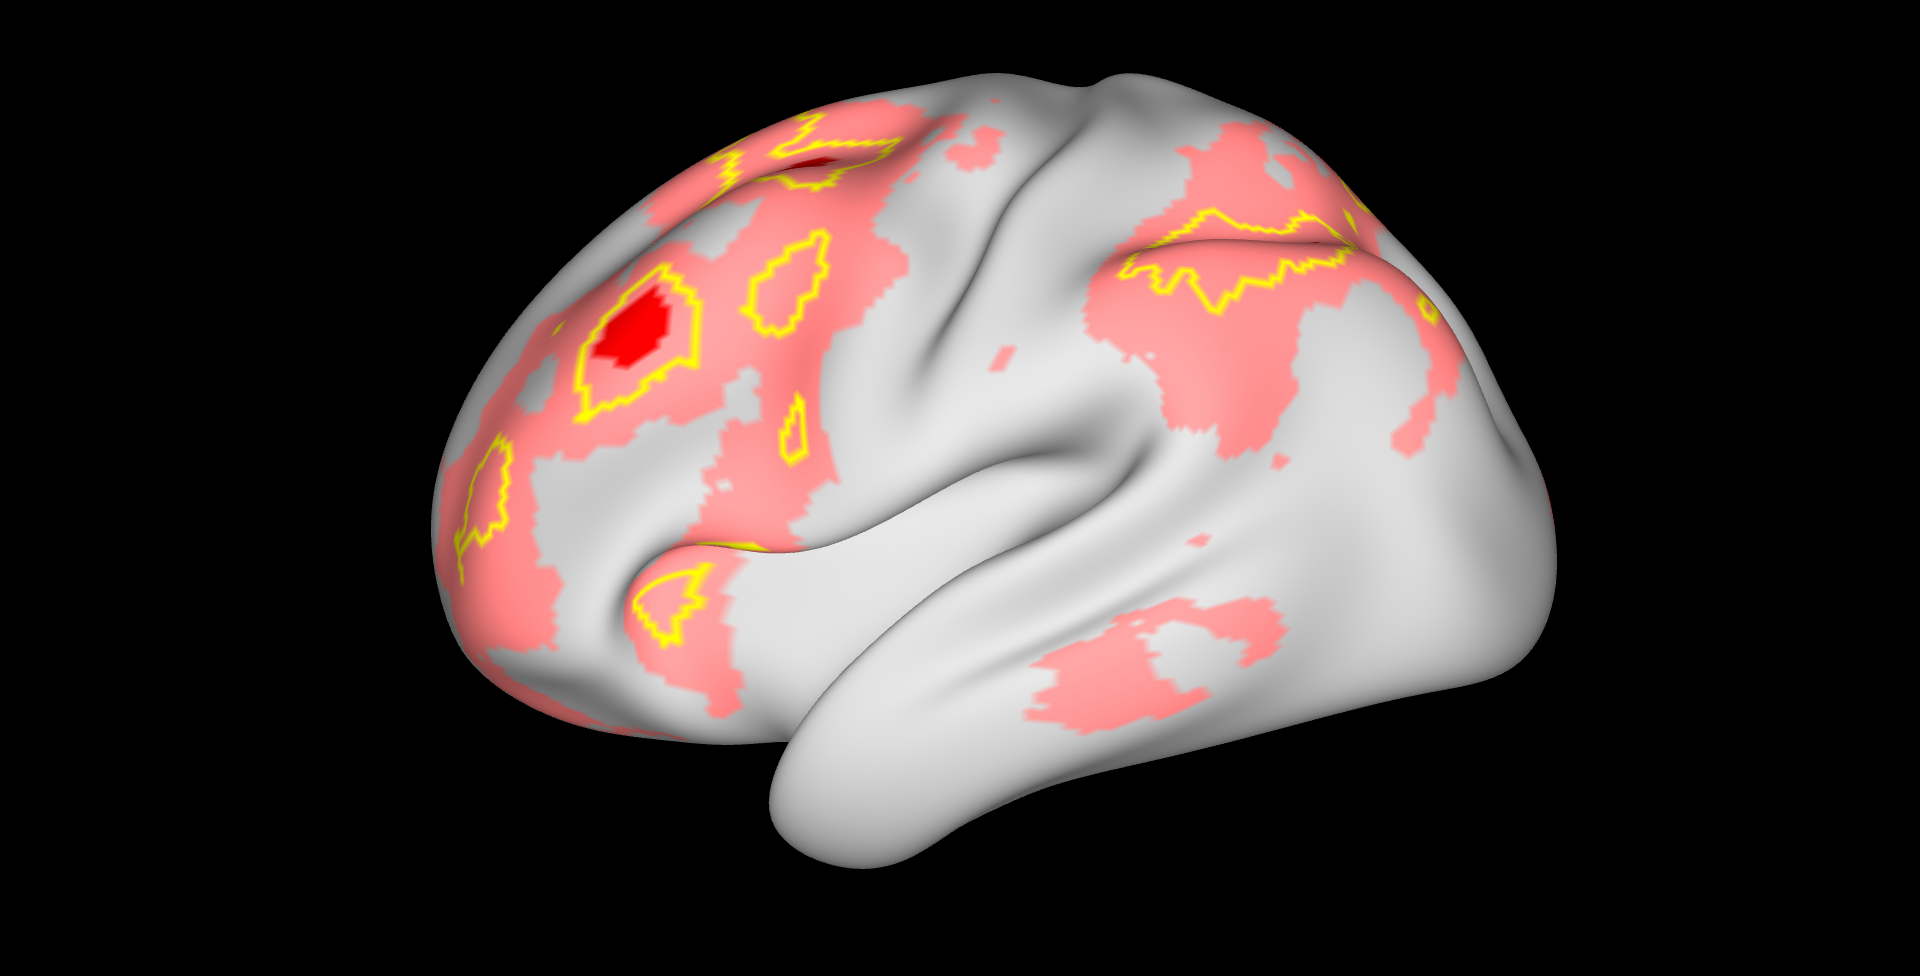

figure; set(gcf,'Visible','on')
color_map = srf_colour(hcp_srf.lh, {lower_set, upper_set, contour}, ...
    {[1,0.5,0.5], [0.9,0,0], [1,1,0]});
srfplot(hcp_srf.lh, color_map, 'left')
title(['SCOPES cope sets, c = ', num2str(c)])

## Varying the threshold

Because the confidence statement holds simultaneously over all `c`, we can sweep `c` and watch the cope sets grow and shrink together without any loss of coverage.

figure; set(gcf,'Visible','on')
t = tiledlayout(2,2,'TileSpacing','Compact');
c_vec = [1, 1.5, 2, 2.5];
for I = 1:length(c_vec)
    [lower_set, upper_set, contour] = ...
        srf_scb2cope(hcp_srf.lh, lower_band.lh, upper_band.lh, xbar.lh, c_vec(I));
    color_map = srf_colour(hcp_srf.lh, {lower_set, upper_set, contour}, ...
        {[1,0.5,0.5], [0.9,0,0], [1,1,0]});
    nexttile;
    srfplot(hcp_srf.lh, color_map, 'left', 1, 0.05, 0)
    title(['c = ', num2str(c_vec(I))])
end
surfscreen